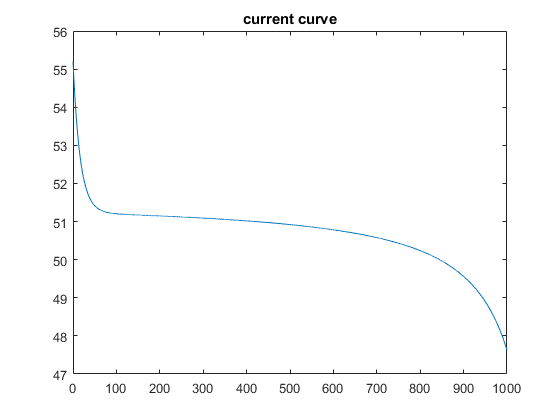

Batt.Batt_Tr = 20;
Batt.Ts = 1e-1;
Batt.E0 = 52.05;
Batt.R = 0.032;
Batt.Qmax = 15.51;
Batt.Qc = 15.51;
Batt.K = 0.02397;
Batt.kc = 0.1;
Batt.kcsat = 0.1;
Batt.A = 4.031;
Batt.B = 4.071;
Batt.C = 0;
Batt.lambda = 1.034;
Batt.current = 10;
Batt.B_ = -exp(-Ts/(Batt_Tr/3));
Batt.A_ = 1+B;

old_old_var = 0;
old_var = 1;
old_res = 0;
old_it_sat = 0;
old_i_filter = 0;
old_current = 10;
max_time = 10/Batt.Ts*100;

tab_current = zeros(1,max_time);
tab_test = zeros(1,max_time);
tab_voltage = zeros(1,max_time);
tab_SOC = zeros(1,max_time);
Load = 2;

for i=1:max_time
    [current,voltage,E1, old_i_filter, old_old_var,old_var, old_res, ...
        old_it_sat,old_current, SOC] = model_batt(Batt,current, Load, ...
        old_i_filter, old_old_var,old_var, old_res, old_it_sat,old_current);
    tab_current(i) = current;
    tab_voltage(i) = voltage;
    tab_SOC(i) = SOC;
%     tab_test(i) = old_old_var;
end
plot(Batt.Ts:Batt.Ts:max_time*Batt.Ts,tab_current)
title('current curve');

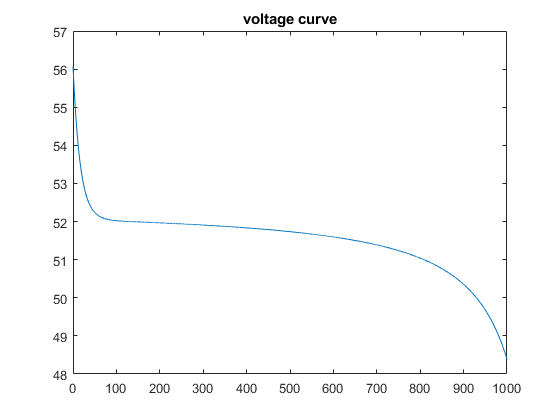

plot(Batt.Ts:Batt.Ts:max_time*Batt.Ts,tab_voltage)
title('voltage curve');

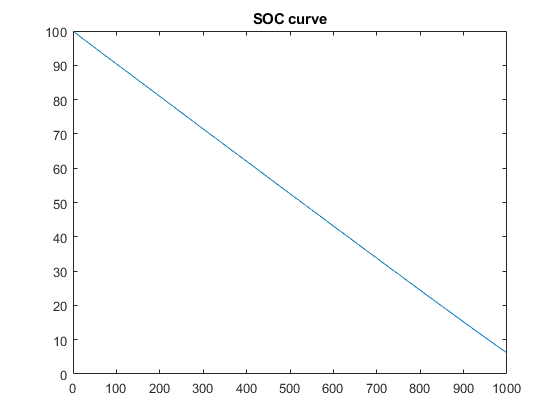

plot(Batt.Ts:Batt.Ts:max_time*Batt.Ts,tab_SOC)
title('SOC curve');

% plot(Batt.Ts:Batt.Ts:10,tab_test)



# Test 2

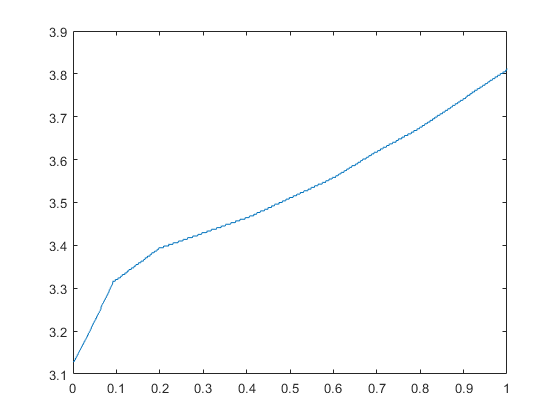

SOC_base = [0    0.0380    0.0920    0.1980    0.4060    0.5320    0.5970    0.6930    0.7990    0.9080    1];
Uoc_base =[3.1340    3.2120    3.3450    3.4330    3.5140    3.5820    3.6160    3.6810    3.7490    3.8300    3.9020];
R_1 = 1e-3*[1.268 1.2080    0.9960    0.7250    0.6340    0.5430    0.4830    0.4530    0.4530    0.4830    0.5430    0.543    0.543 0.543];
SOC_base_2 = [0 0.0050    0.0380    0.0890    0.1370    0.1840    0.2760    0.3860    0.5150    0.6250    0.7610    0.8910    0.9850 1];
R_2 = 1e-3*[7.0340    4.3770    3.1090    1.5090    0.7850    0.5130    0.4830    0.5130    0.5430];
SOC_base_3 = [0    0.0480    0.0720    0.0990    0.1980    0.3990    0.5870    0.8230    1];

SOC = 0:1e-3:1;
Uoc = fixpt_interp1(SOC_base,Uoc_base,SOC,sfix(16),2^-9,sfix(16),...
    2^-8,'Floor');
Rc = fixpt_interp1(SOC_base_2,R_1,SOC,sfix(16),2^-15,sfix(16),...
    2^-15,'Floor');
Rd = fixpt_interp1(SOC_base_3,R_2,SOC,sfix(16),2^-15,sfix(16),...
    2^-15,'Floor');
plot(SOC,Uoc_real)

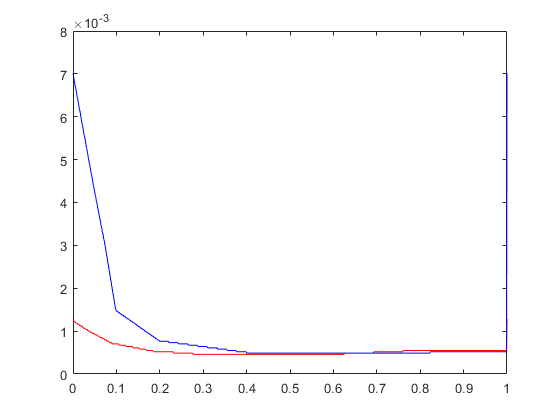

plot(SOC,Rc,'r', SOC,Rd,'b')


val = 0.8;
Pbat = 1000;
ind = find(SOC==val,1);
val_uoc = Uoc(ind)*14.304;
if Pbat <0
val_rbat = Rc(ind);
else
    val_rbat = Rd(ind);
end
    
Ibat = (val_uoc-sqrt(val_uoc^2-4*Pbat*val_rbat))/2/val_rbat

Ibat = 18.6460

Ud = val_uoc-Ibat*val_rbat

Ud = 53.6309